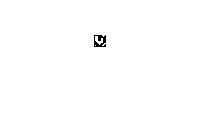

%Second Exercise

clear all;
close all;

A = [0 0 0 0 0 0 0 0 90 90 90 0;
    0 90 90 90 0 0 0 0 0 90 0 0;
    0 90 90 90 0 0 0 0 0 0 0 0;
    0 90 90 90 0 0 0 90 90 0 0 0;
    0 90 90 90 0 0 0 90 90 0 0 0;
    0 90 90 90 0 0 0 90 90 0 0 0;
    0 0 90 90 90 90 90 90 90 0 0 0;
    0 0 0 90 90 90 90 90 90 0 0 0;
    0 0 0 0 90 90 90 0 0 0 90 90;
    0 0 0 0 0 90 0 0 0 90 90 0;
    0 90 0 0 0 0 0 0 90 90 0 0;
    0 0 0 0 0 0 0 0 0 0 0 0];
figure;
imshow(A);

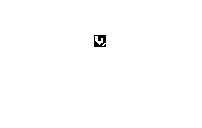

B = (A>1);
figure;
B = bwareaopen(B,5);
A(B==0) = 0;
imshow(B);

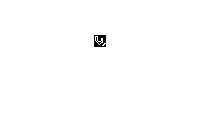

figure;
% fil = imfilter(A,[-1 -2 -1; 0 0 0; 1 2 1])|imfilter(A,[-1 0 1; -2 0 2;-1 0 1]);
fil1 = A - imerode(A,[0 1 0; 1 1 1;0 1 0]); % 8 connectivity
imshow(fil1);

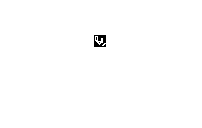

figure;
fil = A - imerode(A,[1 1 1; 1 1 1;1 1 1]); % 4 connectivity
imshow(fil);



[B,C] = bwboundaries(B,8); % 4 or 8
contour = zeros(size(A,1),size(A,2));
for k=1:length(B)
    boundary = B{k};
    for i=1:length(boundary)
        contour(boundary(i,1),boundary(i,2)) = 1;
    end
end
figure;
imshow(contour);

CC = bwconncomp(fil1);
labeled_contours = labelmatrix(CC);
perimeter = [0 0];
for i=1:size(labeled_contours,1)
    for j=1:size(labeled_contours,2)
        if labeled_contours(i,j) == 1
            perimeter(1) = perimeter(1) + 1;
        elseif labeled_contours(i,j) ==2
            perimeter(2) = perimeter(2) + 1;
        end
    end
end
perimeter(1)

ans = 28

perimeter(2)

ans = 6

area = cell2mat(struct2cell(regionprops(C,'Area')))

area =     38     6


centroid = cell2mat(struct2cell(regionprops(C,'Centroid')))

centroid =     5.2895    5.8947   10.5000   10.0000


orientation = cell2mat(struct2cell(regionprops(C, 'Orientation')))

orientation =   -37.7825   39.6902


compacity = zeros(2,1);
magnitude = zeros(4,1);

for i = 1:2
    compacity(i) = perimeter(i)^2/area(i)
end

compacity =    20.6316
         0


compacity =    20.6316
    6.0000



M02 = zeros(2,1);
M20 = zeros(2,1);
M11 = zeros(2,1);
M02(1) = - centroid(1)^2;
M02(2) = - centroid(3)^2;
M20(1) = - centroid(2)^2;
M20(2) = - centroid(4)^2;
M11(1) = - centroid(1)*centroid(2);
M11(2) = - centroid(3)*centroid(4);
for i = 1:size(C,1)
    for j =1:size(C,2)
        if C(i,j) == 1
            M02(1) = M02(1) + i^2/area(1);
            M20(1) = M20(1) + j^2/area(1);
            M11(1) = M11(1) + i*j/area(1);
        elseif C(i,j) == 2
            M02(2) = M02(2) + i^2/area(2);
            M20(2) = M20(2) + j^2/area(2);
            M11(2) = M11(2) + i*j/area(2);
        end
    end 
end

for i=1:2
    magnitude(i*2-1) = ((M02(i)+M20(i)) + sqrt((M20(i)-M02(i))^2 + 4*M11(i)^2))/2;
    magnitude(i*2) = ((M02(i)+M20(i)) - sqrt((M20(i)-M02(i))^2 + 4*M11(i)^2))/2;
end
magnitude

magnitude =    11.6675
   -1.4729
   11.1881
   -9.6047
